# Segmenting an Image

## Thresholding Intensity Values

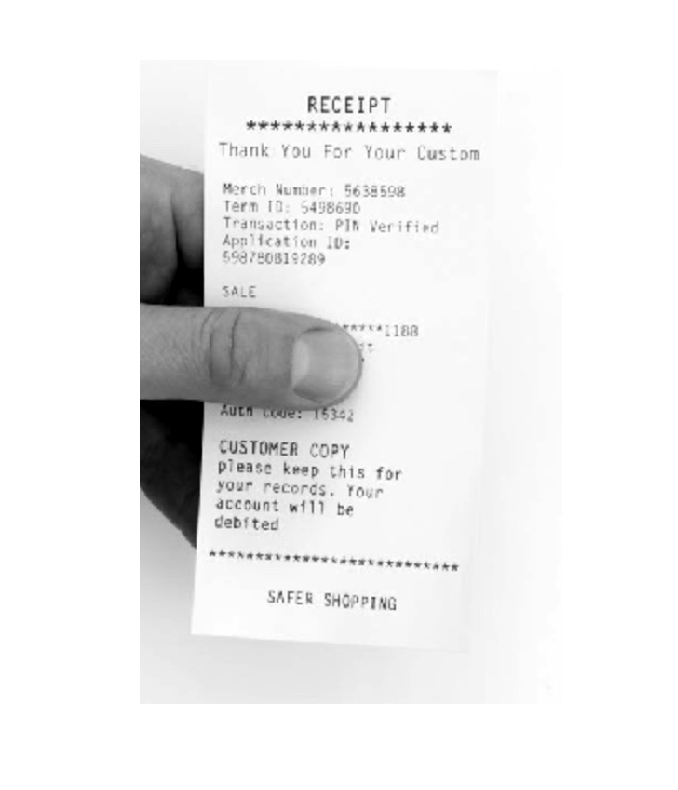

img = imread("img/IMG_001.jpg");
gs = im2gray(img);
gsAdj = imadjust(gs);
imshow(gsAdj)

現在我們想做二值化

最簡單的方法，就是用最大值的一半，來當 threshold

thresh = max(gsAdj, [], "all")/2

thresh = uint8
128

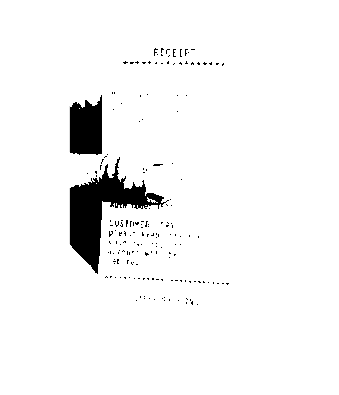

BW = gsAdj > thresh;
imshow(BW)

發現效果不太好，我們看一下 histogram，找個更好的 threshold

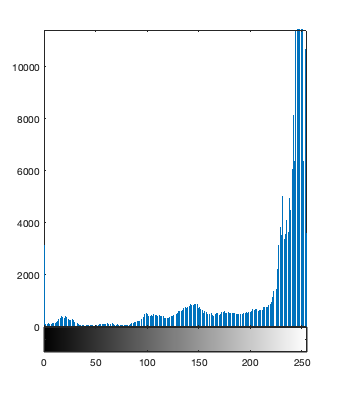

imhist(gsAdj)

可以看到，intensity 集中在 230~ 250 的區域 (其實就是白色背景區)

那我們把 threshold 定為 200，看看效果

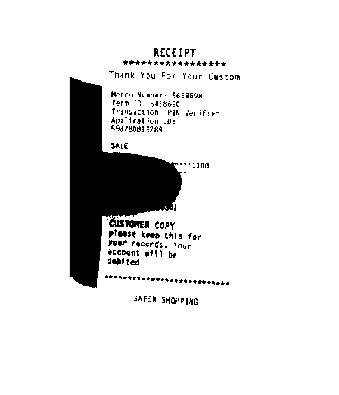

thresh = 200;
BW = gsAdj > thresh;
imshow(BW)

效果比剛剛好了

但試想一下，如果每一張 image 都要這樣搞，那就累死了

所以勢必要有自動化的演算法來幫忙，那 matlab 當然早幫你寫好這些 function 了： `imbinarize()` 

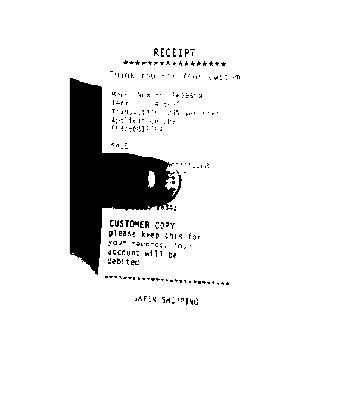

BW = imbinarize(gsAdj);
imshow(BW)

看起來還 ok，但似乎沒有剛剛手動調的好。尤其是上半部的收據文字，不太清楚

default 來說， `imbinarize()` 是用 global thresholding 的方法，那我們可以加上 `"adaptive"` 這個參數，讓他做到 local thresholding (對每個小區域，找出該區域的 threshold，來做二值化)

我們來看看效果

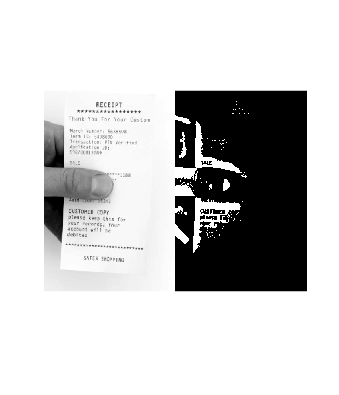

BWadapt = imbinarize(gsAdj, "adaptive");
imshowpair(gsAdj, BWadapt, "montage")

看起來沒啥用。文字現在看起來完全被黑色洗掉 (washed out)，這是為啥？

這是因為，default 來說，matlab 會把較亮的顏色當 foreground (例如白色), 較暗的顏色當作 background (例如黑色)。但在收據的例子中，剛好倒過來了，我們希望黑色當我們的 foreground (主角)，白色是background (配角)

那在 `imbinarize() 這個 function 中，就有 "ForegroundPolarity" 這個參數，可以將 "dark" 設為 foreground。所以來試試：`

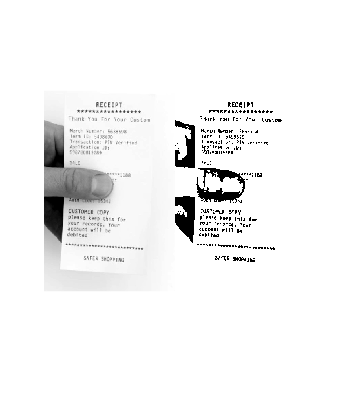

BWadapt = imbinarize(gsAdj, "adaptive", "ForegroundPolarity", "dark");
imshowpair(gsAdj, BWadapt, "montage")

看起來好多了

## Working with a Binary Image

接下來，我們看看 binary image 可以幫我們做什麼事

先看一下剛剛最後的結果：

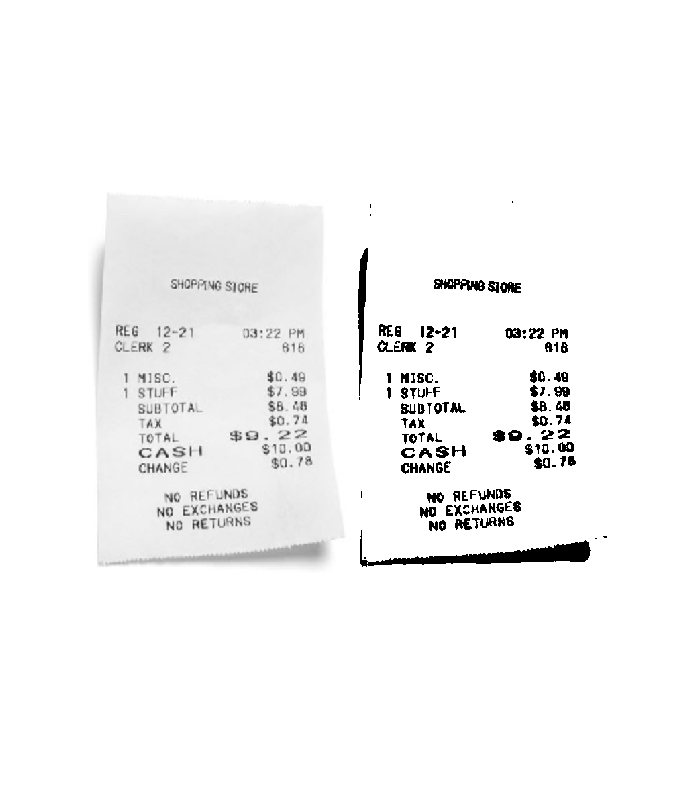

I = imread("img/IMG_006.jpg");
gs = im2gray(I);
gsAdj = imadjust(gs);
BW = imbinarize(gsAdj,"adaptive","ForegroundPolarity","dark");
imshowpair(I,BW,"montage")

首先，我們的目標，是要辨認一張影像是不是 "收據"

那從二值化後的影像，可以發現，他就是一個 0 or 1 的矩陣，有文字出現的地方是 0，背景都是 1

-> 那我如果對這個矩陣取 row sum，就能知道哪一列有文字，哪一列都是背景了！

-> 有文字的列， row sum 會較小 (因為文字的灰階值是 0, 背景灰階值是 1); 背景的列，row sum 會較大

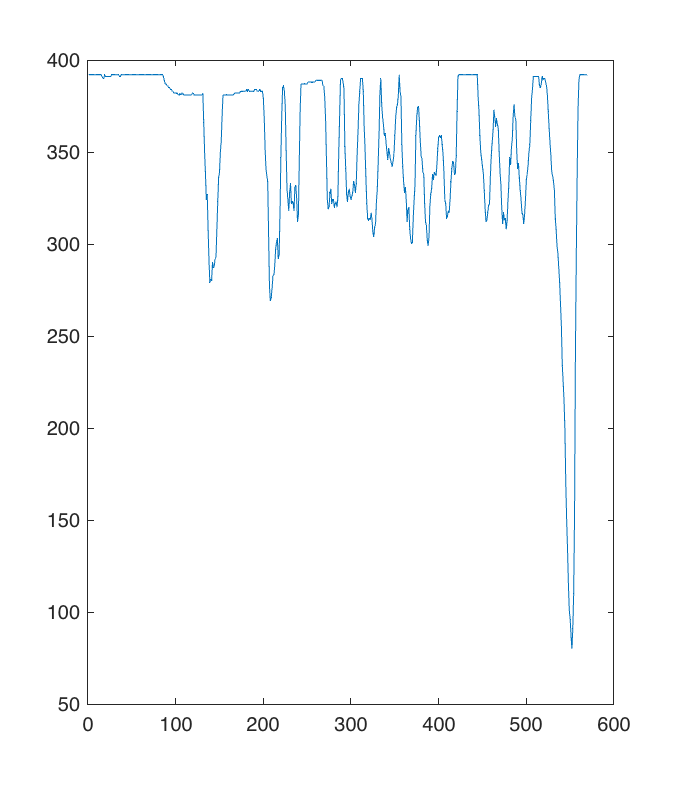

S = sum(BW, 2); % row sum
plot(S)

可以發現，都對應的很好，往下降下來的 peak，就都是文字會出現的 row

## Comparing Row Sums

在現實世界中，總是沒有理論上來的美好

我們來看看幾張 image，都會讓我們剛剛的 algorithm (i.e. 用 row sum 來找文字) 失效

### noise image & filtering nose post-process

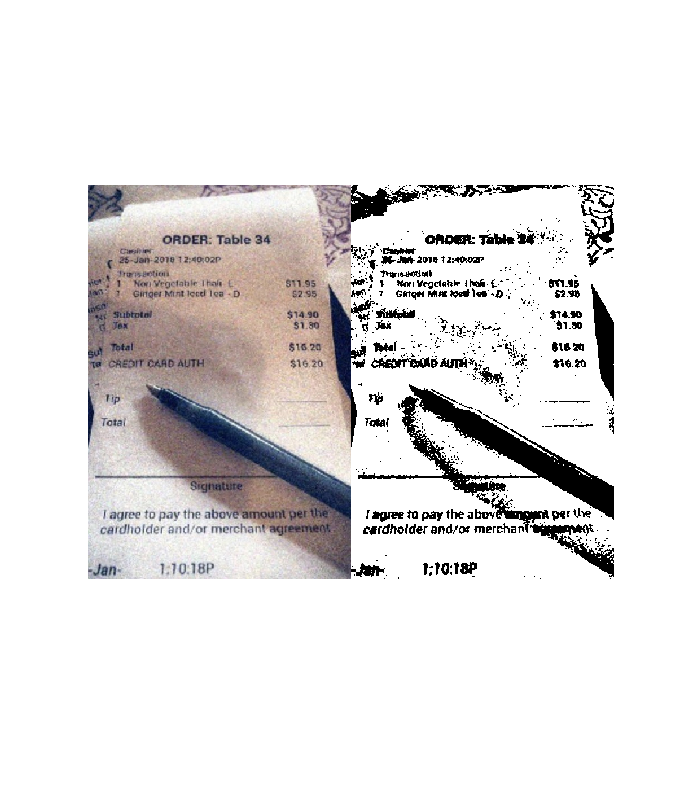

I = imread("img/IMG_007.jpg");
gs = im2gray(I);
gsAdj = imadjust(gs);
BW = imbinarize(gsAdj,"adaptive","ForegroundPolarity","dark");
imshowpair(I,BW,"montage")

可以看到，二值化後，很多 noise 的黑點，這導致做 row sum 時會失真

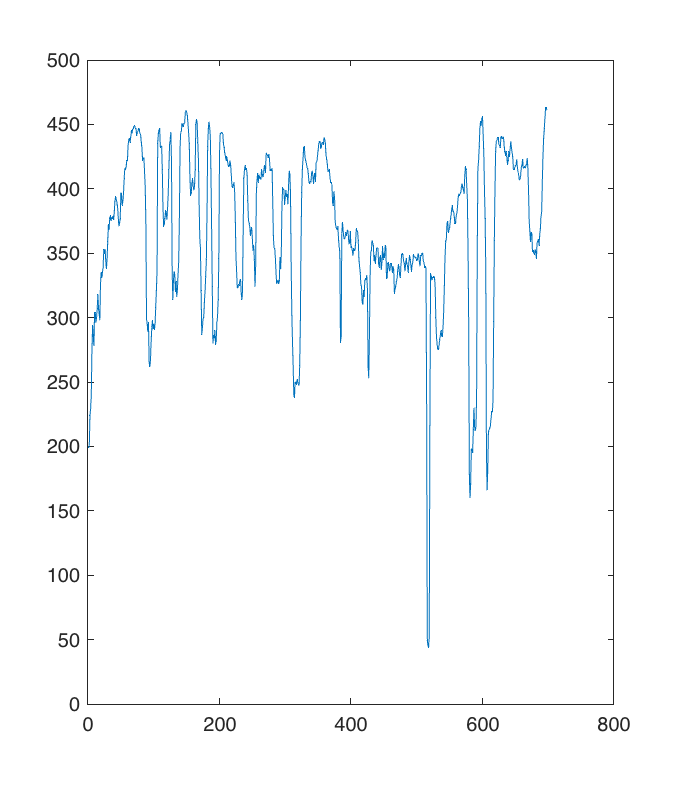

S = sum(BW,2);
plot(S)

解決方法，就是 remove noise

先做個 均值 filter

H = fspecial("average",3) % average, gaussian, laplacian, sobel, ...

H =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


然後，對剛剛的影像做 filter，用的是 `fspecial()` 函數 (我猜， f 是 filter 的意思，special 就空間吧？)

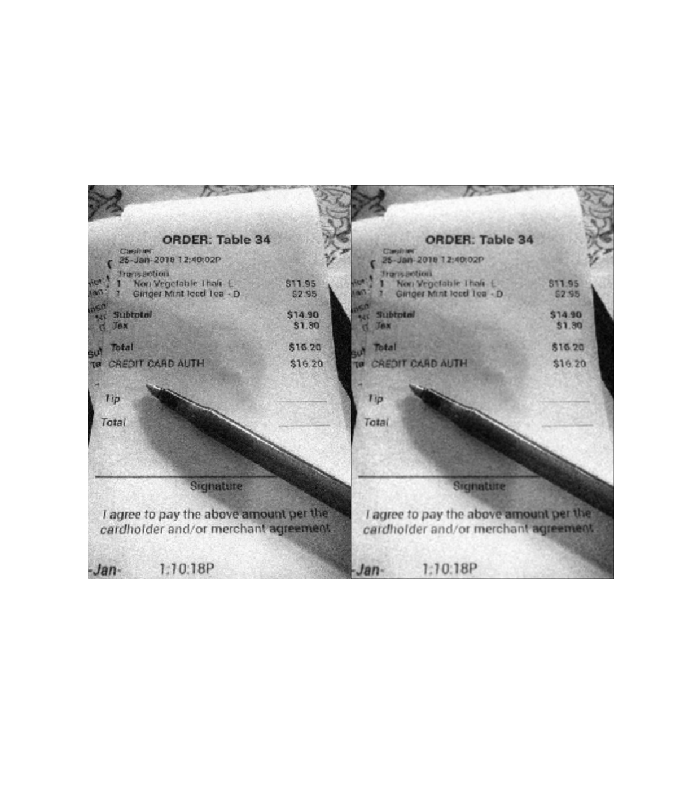

gssmooth = imfilter(gs,H);
imshowpair(gs, gssmooth, "montage")

單看此圖，還不明顯，但二值化後，就很明顯了：

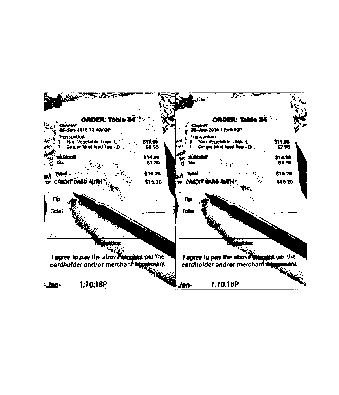

BW = imbinarize(gs, "adaptive", "ForegroundPolarity","dark");
BWsmooth = imbinarize(gssmooth,"adaptive","ForegroundPolarity","dark");
imshowpair(BW, BWsmooth, "montage")

可以發現，剛剛的那些 noise 去掉不少

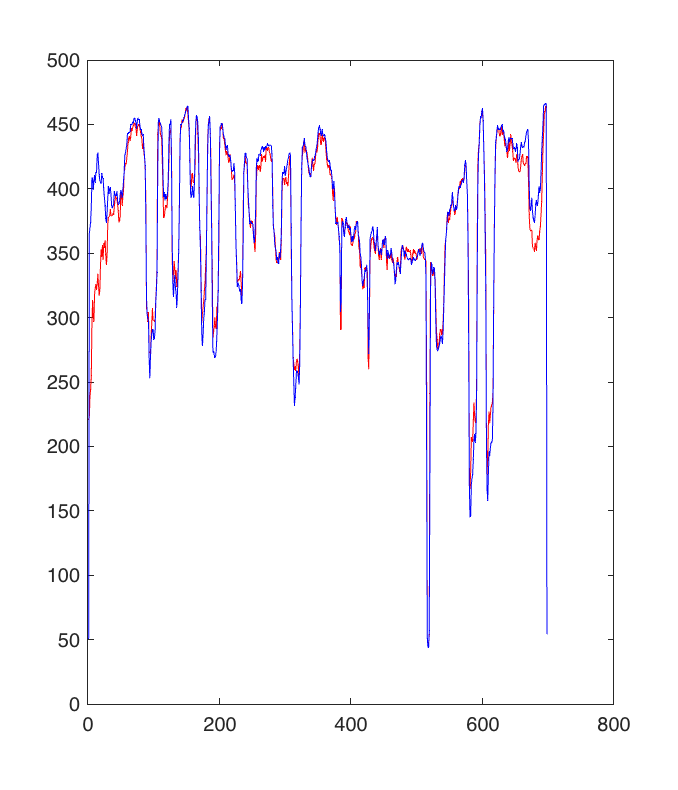

plot(sum(BW, 2), "r-")
hold on
plot(sum(BWsmooth, 2), "b-")
hold off

再來看到這張：

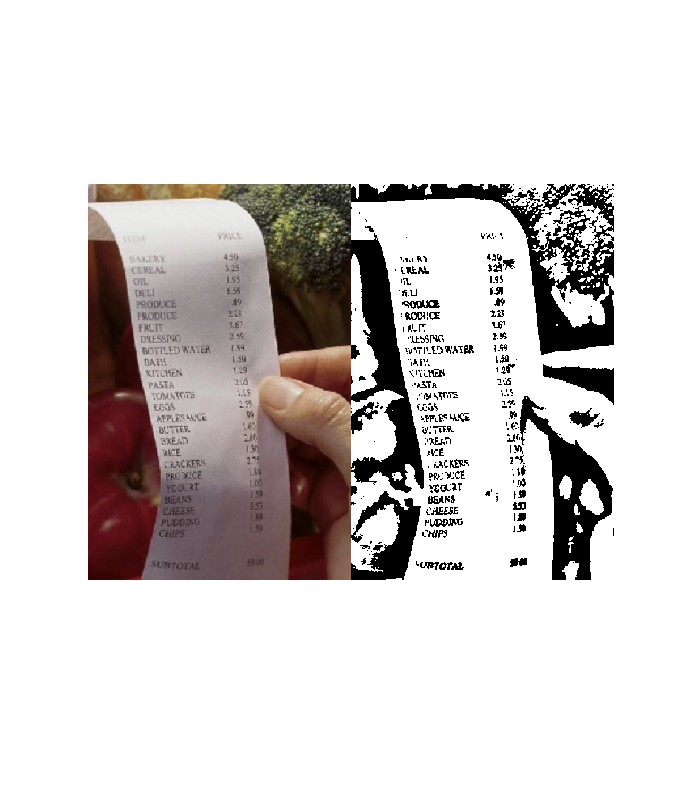

I = imread("img/IMG_010.jpg");
gs = im2gray(I);
gsAdj = imadjust(gs);
BW = imbinarize(gsAdj,"adaptive","ForegroundPolarity","dark");
imshowpair(I,BW,"montage")

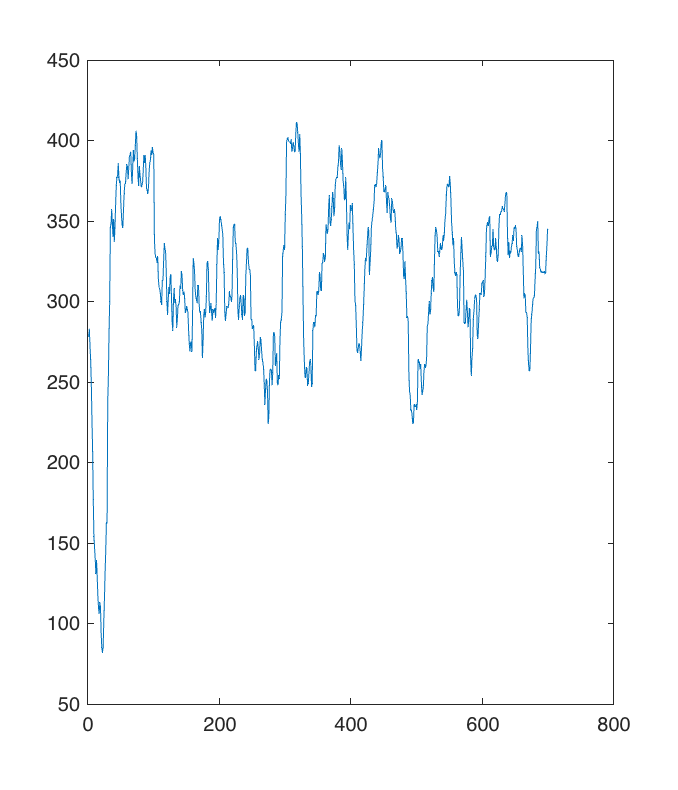

S = sum(BW,2);
plot(S)

可以看到，背景的影響很巨大，這也讓 row sum 失真 -> remove background 會是該做的後處理

同樣的問題，也出現在這張：

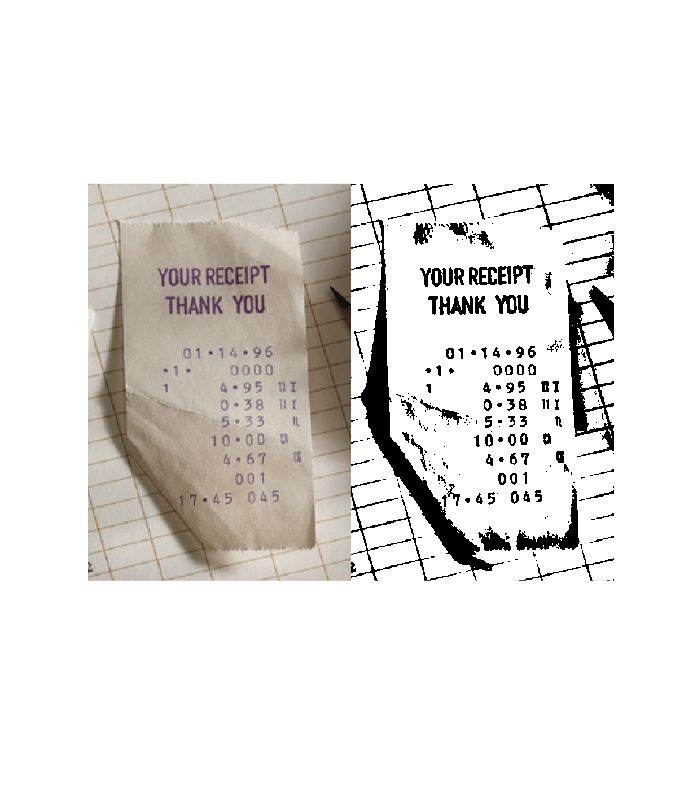

I = imread("img/IMG_002.jpg");
gs = im2gray(I);
gsAdj = imadjust(gs);
BW = imbinarize(gsAdj,"adaptive","ForegroundPolarity","dark");
imshowpair(I,BW,"montage")

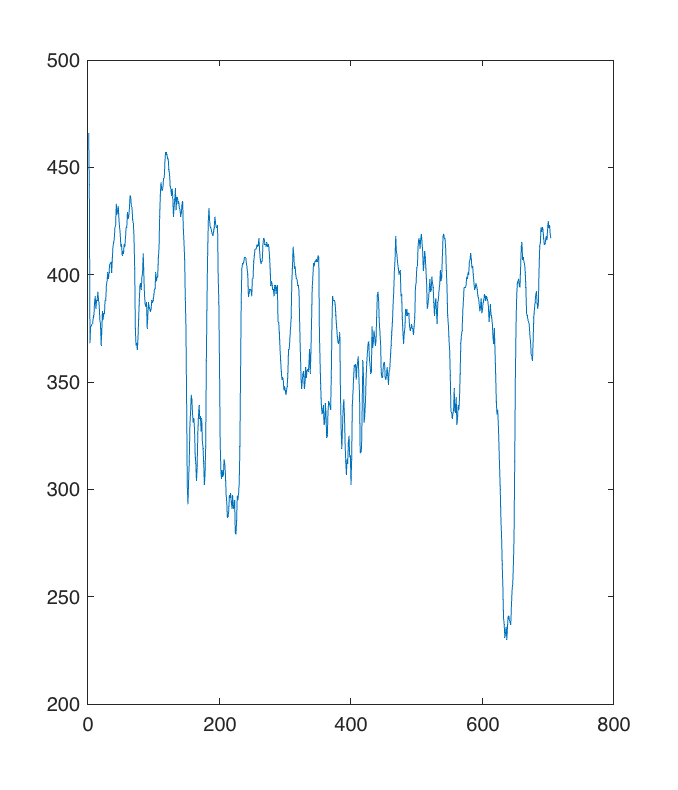

S = sum(BW,2);
plot(S)

## Filtering noise

回到剛剛 IMG_007.jpg 的例子